m = 5 ;  k = 1 ;  b = 0.5 ;
num = [1] ;  den = [m b k] ;
sys = tf(num, den)

sys =
 
          1
  -----------------
  5 s^2 + 0.5 s + 1
 
Continuous-time transfer function.
Model Properties


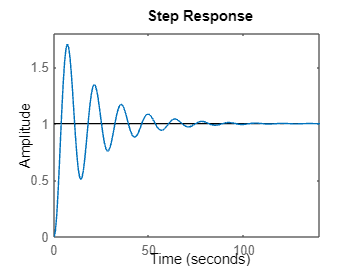

step(sys)

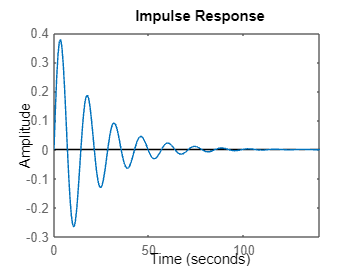

impulse(sys)

const= [5, 0.5, 1];
root = roots(const)

root =   -0.0500 + 0.4444i
  -0.0500 - 0.4444i


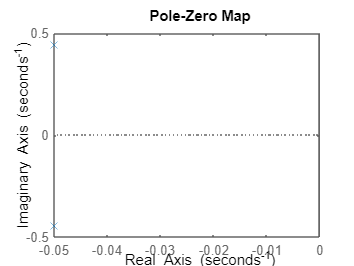

pzmap(sys)

step_info = stepinfo(sys);
settling_time = step_info.SettlingTime

settling_time = 78.1524